# Fase 5: Cribado de calidad Procesado de Datos e Imágenes

close all; clear all;
T=readtable('metadata.csv');
[N, P]=size(T);
variables=T.Properties.VariableNames;

***Glaucoma:***

- 0:Sano 

- 1:Glaucoma

***Quality:***

- 0:No revisada 

- 1:Bajo contraste 

- 2:Desenfoque 

- 3:Ruido 

- 4:Calidad correcta

### 1.Extracción de las caracteristicas de las imagenes

Para obtener los diferentes parámetros de cada imagen, es fundamental tener la ubicación de todas ellas. Para lograrlo, utilizamos la función "fullfile" junto con un bucle para generar una cadena de strings que contenga las ubicaciones de las 1570 imágenes en el conjunto de datos.

ImagePath=fullfile('images');
ImageLocation='';
for i=1:N
    str=string(T{i,1});
    ImagePathFinal=fullfile(ImagePath,str);
    ImageLocation=[ImageLocation,ImagePathFinal];
end
ImageLocation=[ImageLocation(2:end)];

Se han extraido los siguientes parametros de las imagenes del dataset: 

- Entropia, desviación estandar, rángo dinámico, media del resultado de la transformada de laplace, intensidad máxima y la varianza.

for i=1:N
    I=imread(ImageLocation(1,i)); 
    Igray=im2gray(I);
    T.Entropy(i,1)=entropy(double(Igray));%entropia
    T.Contrast(i,1)=std2(double(Igray)); %desviación estándar de los valores de píxeles en una imagen en escala de grises
    Imin=min(I(:));Imax=max(I(:));
    T.TarteDinamiko(i,1)=Imax-Imin; %tarte dinamiko (las de bajo contraste lo tienen bajo)
   
    %La transformada de Laplace para la detección de las ertzak
    LaplazFilter=[0 1 0; 1 -4 1; 0 1 0];%
    L=imfilter(I,LaplazFilter); %double(I)
    T.Laplacianmean(i,1)=mean(double(L(:)));%media de los bordes %comprobar quitando
    T.Laplacianmax(i,1)=max(double(L(:)));%valor maximo
    T.Laplacianvar(i,1)=var(double(L(:)));%varianza
end


[N,P]=size(T);
variables=T.Properties.VariableNames;

### 2.Exploratory data analysis

Missingness map

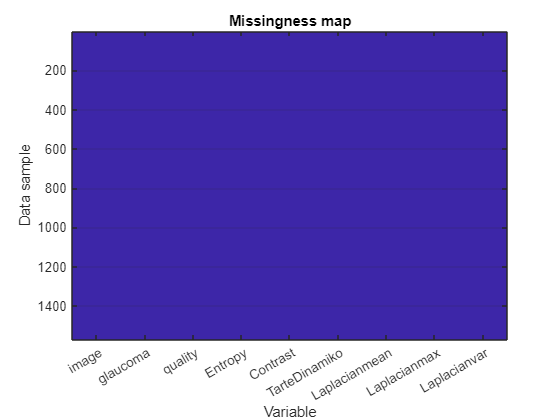

close all;
imagesc(ismissing(T));
xticks(1:P);xticklabels(variables);
title('Missingness map');xlabel('Variable');ylabel('Data sample');set(gca,"XGrid","off","YGrid","on");

No hay dato alguno que falte.

Distribución de todas las imagenes

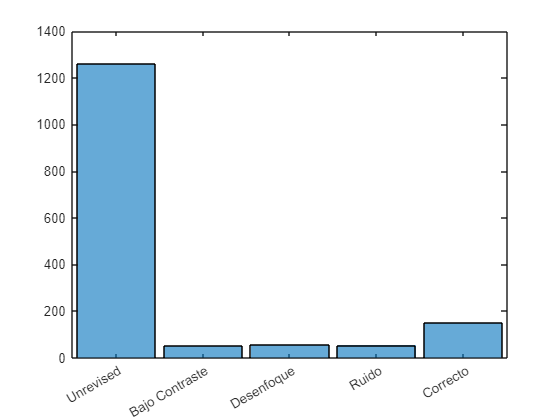

TQcategorical=categorical(T.quality,[0,1,2,3,4],{'Unrevised','Bajo Contraste','Desenfoque','Ruido','Correcto'});
histogram(categorical(TQcategorical))

Distribución de las imagenes revisadas

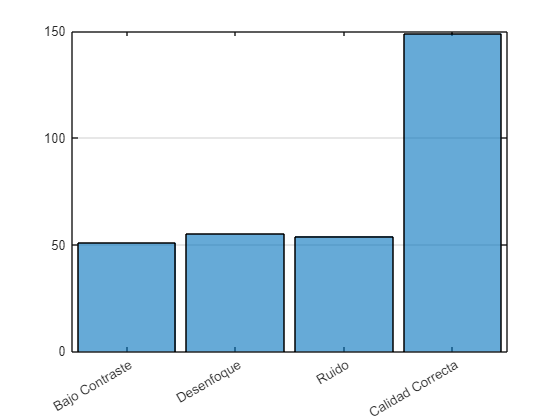

close all;
TQcategorical2=categorical(T.quality,[1,2,3,4],{'Bajo Contraste','Desenfoque','Ruido','Calidad Correcta'});
histogram(categorical(TQcategorical2))
set(gca,"XGrid","off","YGrid","on");

Correlation matrix

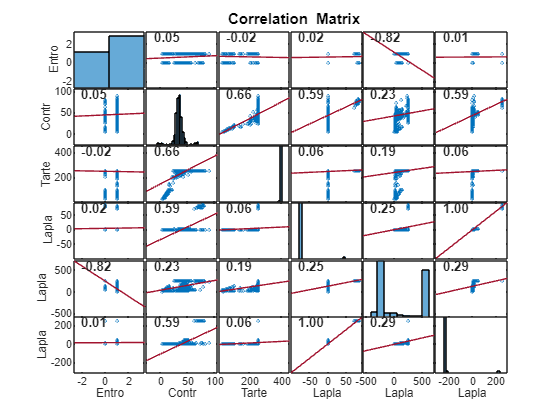

columns={'Entropy','Contrast','TarteDinamiko','Laplacianmean','Laplacianmax','Laplacianvar'};
Tcorr=T(:,columns);
figure;
corrplot(Tcorr)

Como bien se aprecia en la matriz de correlación existen dos variable con un coeficiente de correlacion de 1, lo que significa que se esta añadiendo información redundante. Por tanto una de las dos variables sera eliminada de la tabla.

T.Laplacianmean=[];
[N, P]=size(T);%nuevas dimensiones
variables=T.Properties.VariableNames;

Histogramas de las distintas calidades

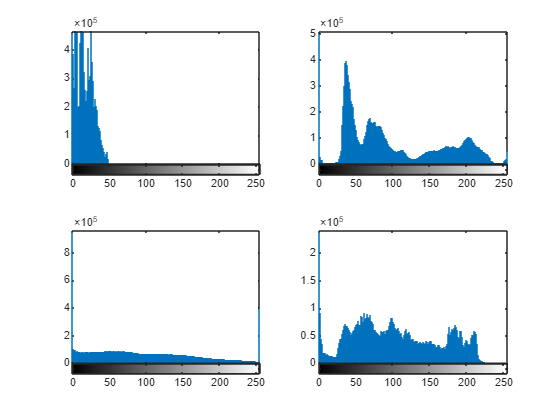

close all;
IBajoContraste=imread("images\image_0204.jpg");ICorrect=imread("images\image_0003.jpg");IRuido=imread("images\image_0230.jpg");IDesenfoque=imread("images\image_0023.jpg");

subplot(2,2,1);imhist(IBajoContraste)
subplot(2,2,2);imhist(ICorrect)
subplot(2,2,3);imhist(IRuido)
subplot(2,2,4);imhist(IDesenfoque)

Para el desarrollo del modelo tan solo se utilizaran las imagenes revisadas. Más tarde el modelo desarrollado servira para predecir la calidad de las imagenes no revisadas . Debido a esto, crearemos una nueva tabla con las filas de las imagenes revisadas y otre para las no revisadas.

*Tabla con tan solo las imagenes revisadas*

Trevised=T;
for i=N:-1:1
    if(Trevised.quality(i)==0)
        Trevised(i,:)=[];
    end
end

*Tabla sin las imagenes revisadas*

Tunrevised=T;
for i=N:-1:1
    if(Tunrevised.quality(i)~=0)
        Tunrevised(i,:)=[];
    end
end

### 3.Machine Learning

Al haber un desbalance entre clases y a fin de evitar que esto tenga efecto en las predicciones de clase, se ha decidido realizar una tabla con todas las clases estratificadas.

TStratified=Trevised;

NBajoCont=sum(Trevised.quality==1);
FindBajoCont=find(Trevised.quality==1);FindBajoCont=sort(FindBajoCont,'descend');%Clase con menos cantidad

NCorrecta=sum(Trevised.quality==4); Dif=NCorrecta-NBajoCont;
FindCorrecta=find(Trevised.quality==4);FindCorrecta=sort(FindCorrecta,'descend');
FindCorrect=FindCorrecta(1:Dif)

FindCorrect =    309
   308
   307
   306
   304
   303
   302
   300
   293
   292


NDesenf=sum(Trevised.quality==2);Dif=NDesenf-NBajoCont;
FindDesenf=find(Trevised.quality==2);FindDesenf=sort(FindDesenf,'descend');
FindDesenf=FindDesenf(1:Dif)

FindDesenf =    297
   296
   283
   281


NRuido=sum(Trevised.quality==3);Dif=NRuido-NBajoCont;
FindRuido=find(Trevised.quality==3);FindRuido=sort(FindRuido,'descend');
FindRuido=FindRuido(1:Dif)

FindRuido =    305
   298
   295


Delete=vertcat(FindRuido,FindDesenf,FindCorrect);Delete=sort(Delete,'descend')

Delete =    309
   308
   307
   306
   305
   304
   303
   302
   300
   298


Delete=transpose(Delete);

Delete =    309   308   307   306   305   304   303   302   300   298   297   296   295   293   292   291   290   289   287   284   283   282   281   277   276   274   273   272   267   265   264   263   260   255   252   250   249   248   247   246   245   237   236   234   232   231   230   229   226   224


for i=1:105
    j=Delete(1,i);
    TStratified(j,:)=[];
end

Una vez conseguida la tabla con todas las clases balanceadas se pasara a entrenar un modelo de clasificación

Con la aplicación de MATLAB "classification learner"  se entrenaran diversos modelos y se seleccionarán los que mejor predicciones hagan. La division de datos se realizara por medio del metodo Cross validation (en 5 iteraciones).

load('FineKNNCrossValidation.mat');
[ypred,scores] = FineKNNCrossValidation.predictFcn(Tunrevised);%primera predicción
ypred

ypred =      4
     4
     4
     4
     4
     2
     4
     4
     4
     4


Introducción de las predicciones en las tablas.

Tunrevised.quality=ypred;
Tfinal=vertcat(Trevised, Tunrevised);
Tfinal=sortrows(Tfinal,'image')

Tfinal = 1570×9 table
          image           glaucoma    quality    Entropy     Contrast    TarteDinamiko    Laplacianmean    Laplacianmax    Laplacianvar
    __________________    ________    _______    ________    ________    _____________    _____________    ____________    ____________

    {'image_0001.jpg'}       0           4        0.55237     47.479          255            0.62066            37            1.5931   
    {'image_0002.jpg'}       0           4        0.54686     42.651          255            0.65224            38            1.6956   
    {'image_0003.jpg'}       0           4        0.54767     42.894          255            0.79286            30            2

Tabla con imagenes de calidad correcta.

TCorrect=Tfinal;
for i=N:-1:1
    if(TCorrect.quality(i)~=4)
        TCorrect(i,:)=[];
    end
end
TCorrect.Entropy=[];TCorrect.Contrast=[];TCorrect.TarteDinamiko=[];TCorrect.Laplacianmean=[];TCorrect.Laplacianmax=[];TCorrect.Laplacianvar=[];

writetable(TCorrect,'TCorrect.csv')